clear all, close all;
addpath('..\');


SAMPLING_FREQ = (50*16*16);
BUFFER_LEN = 2048;
FREQ = SAMPLING_FREQ*(0 : BUFFER_LEN-1)/BUFFER_LEN;
MAIN_FREQ_INDEX = 9;
csv_read;

out = sim("hdl_model.slx")

out =   Simulink.SimulationOutput:

                   tout: [70401x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim_FFT = out.yout{1}.Values;
sim_RMS = out.yout{2}.Values;
sim_MAX = out.yout{3}.Values;
sim_MIN = out.yout{4}.Values;
sim_THD = out.yout{5}.Values;


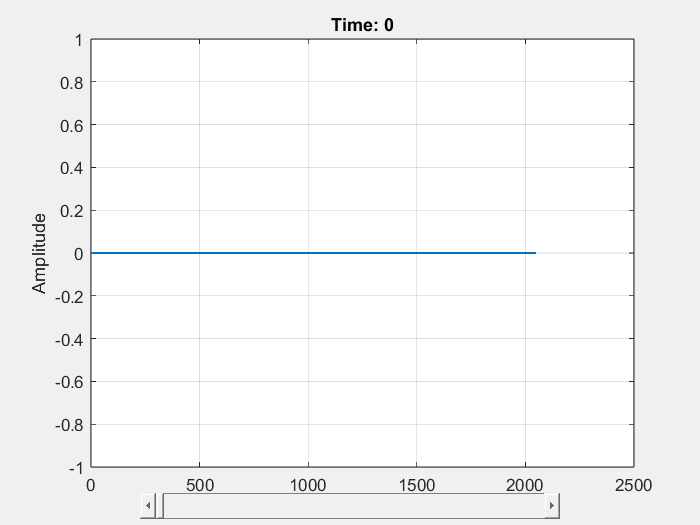

slidePlotTimeSeries(sim_FFT);

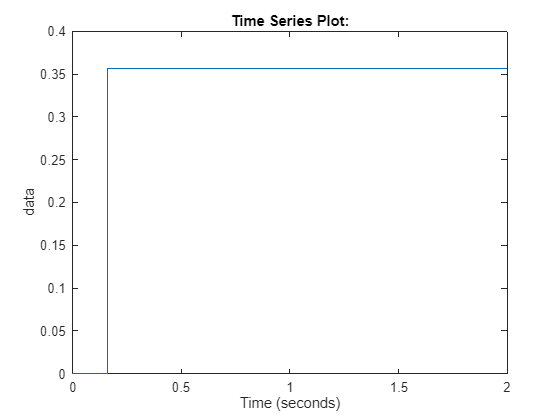


figure;
plot(sim_RMS);

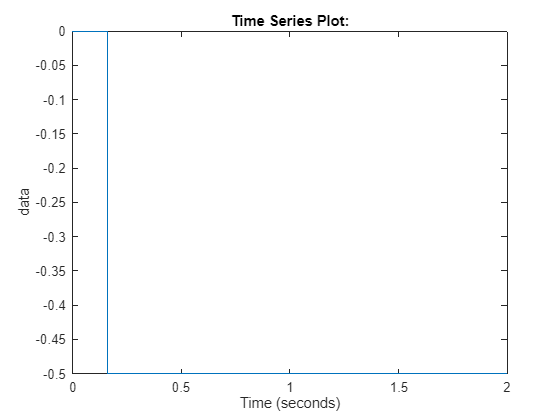


figure;
plot(sim_MAX);

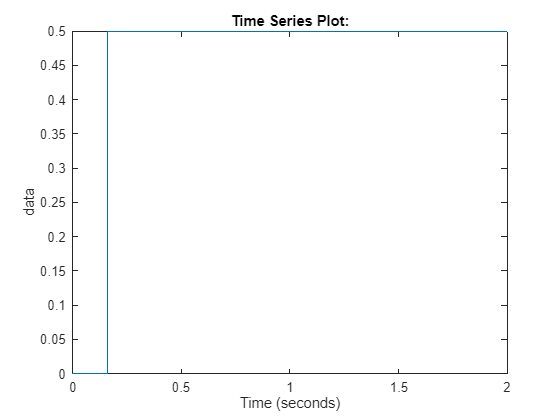


figure;
plot(sim_MIN);

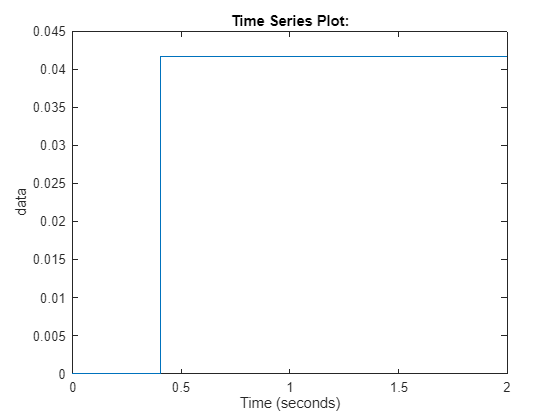


figure;
plot(sim_THD);